# Project 3 - Matlab - Covid-19 Pandemic

*Pablo Martínez, Oriol Bustos*

In this third and last project..

%addpath(['C:/Users/oriol/Escritorio/[4] Estudios/[1] EBM/[1.S8]/[4.1.2] DPVL/data_lab/Project 3/Pandemic/'])
%addpath(tudirectorio)

## 1. Density effect

d = linspace(0.01, 0.5, 4);
plot_epidemic_curves_check = false
for i=1:4
    result = Pandemic_Matlab_ex1(d(i), plot_epidemic_curves_check);
end
result

## 2. Create a movie

d = 0.01
plot_epidemic_curves_check = false
result = Pandemic_Matlab_ex2(d, plot_epidemic_curves_check);

movie(result.M)

## 3. The Rho number and Re-infections

Result = Pandemic_Matlab_ex3(Input, false);
infection_matrix = Result.infection_matrix;
% Finding the Rho number: 
Rho_vals = zeros(size(infection_matrix(1,:)));
Reinfections = zeros(size(infection_matrix(1,:)));
for i=1:length(infection_matrix(:,1))
    Rho_vals(1,i) = sum(infection_matrix(i,:));
    Reinfections(1,i) = sum(infection_matrix(:,i));
end
mean_val = mean(Rho_vals);
reinf_num = sum(Reinfections);
disp(mean_val);
disp(reinf_num);

## 4. Finding Regrothws

fcorrer para diferentes escenarios la curva de infectados y con findpeaks contar el numero de picos, si hay vairos hay regrowths

d = linspace(0.01, 0.5, 4);
confinement = [0, 1];
confined_pc_values = [50, 80];
combinations = [];

% generate combinations
for density = d
    for conf = confinement
        if conf == 0
            combinations = [combinations; density, 0, 1]; 
        else
            for confined_pc = confined_pc_values
                combinations = [combinations; density, 1, confined_pc];
            end
        end
    end
end
peakCounts = zeros(size(combinations, 1), 1);

for i = 1:size(combinations, 1)
    density = combinations(i, 1);
    conf = combinations(i, 2);
    confined_percent = combinations(i, 3);

    result = Pandemic_Matlab_ex4(density, false, conf, confined_percent);
    [peaks, ~] = findpeaks(result.infected);
    peakCounts(i) = numel(peaks);
end

disp('Combinations and their peak counts:');
for i = 1:size(combinations, 1)
    fprintf('Density: %.2f, Confinement: %d, Confined Percent: %d, Peaks: %d\n', ...
        combinations(i, 1), combinations(i, 2), combinations(i, 3), peakCounts(i));
end


## 5. Opening the Gaps

max_gap = 5; % give a value for the maximum gap size desired
max_iter_mean = 5; % give a value for the number of iterations with the same gap 
gapsize = 1:max_gap; % number of different gap values tried 
counter = 0; % optional

max_mat = zeros(max_iter_mean,max_gap); % recorded values of maximum infections

for it_no = 1:max_iter_mean
    maxInfectedTime = zeros(1,max_gap); % recording the times for the maximum infections
    for i = gapsize
        % Redefining the input to change in each iteration the gap size:
        Input = struct('max_iter', max_iter, 'people', people,...,
            'size_x', size_x,...,
            'inner_border', 1,...,
            'gap', i,...,
            'sick_pc', sick_pc,...,
            'max_sick_time', max_sick_time,...,
            'confinement', 0,...,
            'confined_pc',0.5,...,
            'do_plot', 1);
        Result = Pandemic_Matlab_ex5(Input, false); % run the function 
        infected = Result.infected; % grab the infected pop 
        [max,max_index] = max(infected); % maximum value and its position in the array
        maxInfectedTime(i) = max_index; % adding the time at which maximum is reached
        counter = counter+1; 
        disp(counter);
    end
    max_mat(it_no,:) = maxInfectedTime; %adding to the max_mat the mmaximum ifected times
end


figure(1);
plot(gapsize, mean(maxInfectedTime,1),'-o'); % plotting the mean of each column for each gap size
title('Mean maximum infection time against gap Linear plot') 
xlabel('Gap');
ylabel('Time to Max Infected');

figure(2); 
boxplot(gapsize, mean(maxInfectedTime,1)); % same but with boxplots
title('Mean maximum infection time against gap Box plots') 
xlabel('Gap');
ylabel('Time to Max Infected');

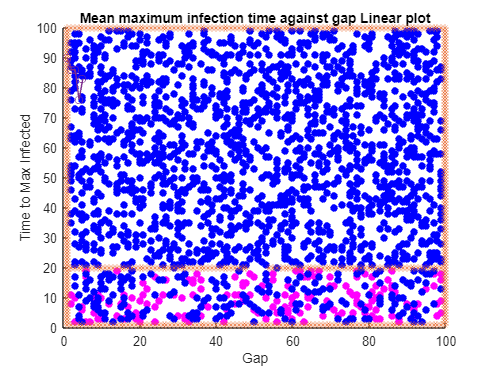

movility = 0.01:0.1:1;
maxInfectedTime = zeros(10,1);
iter = 1;
for mov = movility
    people= round((size_x)^2*d);
    Input = struct('max_iter', max_iter, 'people', people,...,
        'size_x', size_x,...,
        'inner_border', 1,...,
        'gap', 3,...,
        'sick_pc', sick_pc,...,
        'max_sick_time', max_sick_time,...,

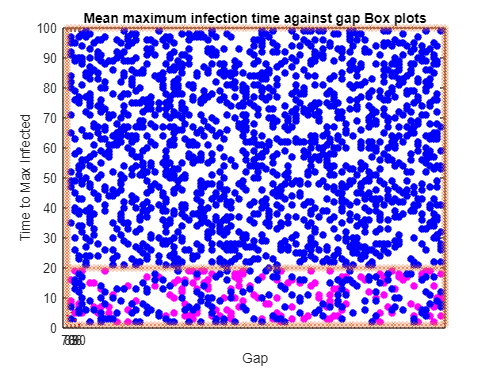

        'confinement', 1,...,
        'confined_pc',mov,...,
        'do_plot', 0);
    Result = Pandemic_Matlab_ex5(Input, false);
    infected = Result.infected;
    [max,max_index] = max(infected);

    maxInfectedTime(x) = max_index;
    iter = iter+1;
end

figure(1);
plot(movility, maxInfectedTime)
title('Mean maximum infection time against movility Linear plot') 
xlabel('Movility');
ylabel('Time to Max Infected');

figure(2);
boxplot(movility, maxInfectedTime)
title('Mean maximum infection time against movility Box plots') 
xlabel('Movility');
ylabel('Time to Max Infected');

## 6. SIR Model

aaa

density = 0.2;

result = Pandemic_Matlab_ex6(density, false);
disp(length(result.non_infected))
time_index = floor(length(result.non_infected)/ 3);

S = result.non_infected(time_index);
I = result.infected(time_index);
R = result.recovered(time_index);

values = [S I R];
disp(values)
figure;
pie(values, {'Susceptible', 'Infected', 'Recovered'});
titlesss = sprintf('SIR Model Distribution at t = %g a.u.', time_index);
title(titlesss);

## 7. Surface Plot

aaa

## 8. Infection Probability

aaa

## 9. Extra Exercise (Optional)